ans = 'B17'

ans = 'B20'

ans = 'B28'

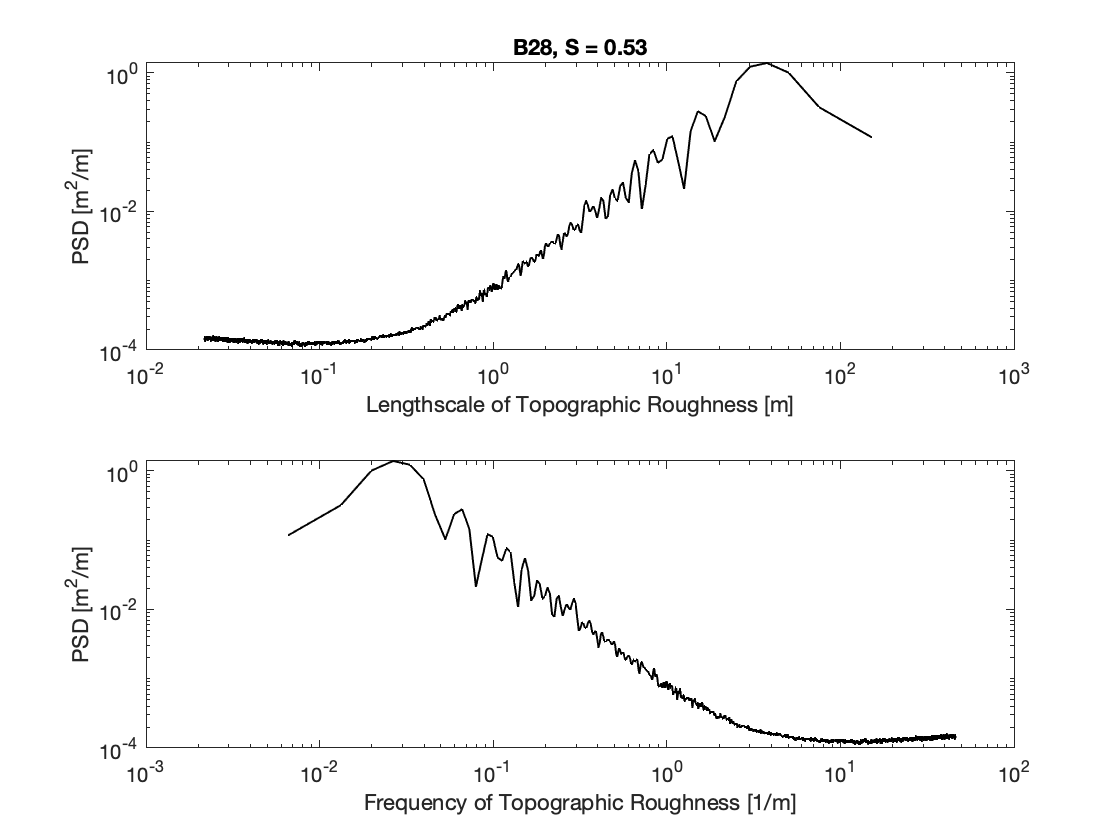

ans = 'V14'

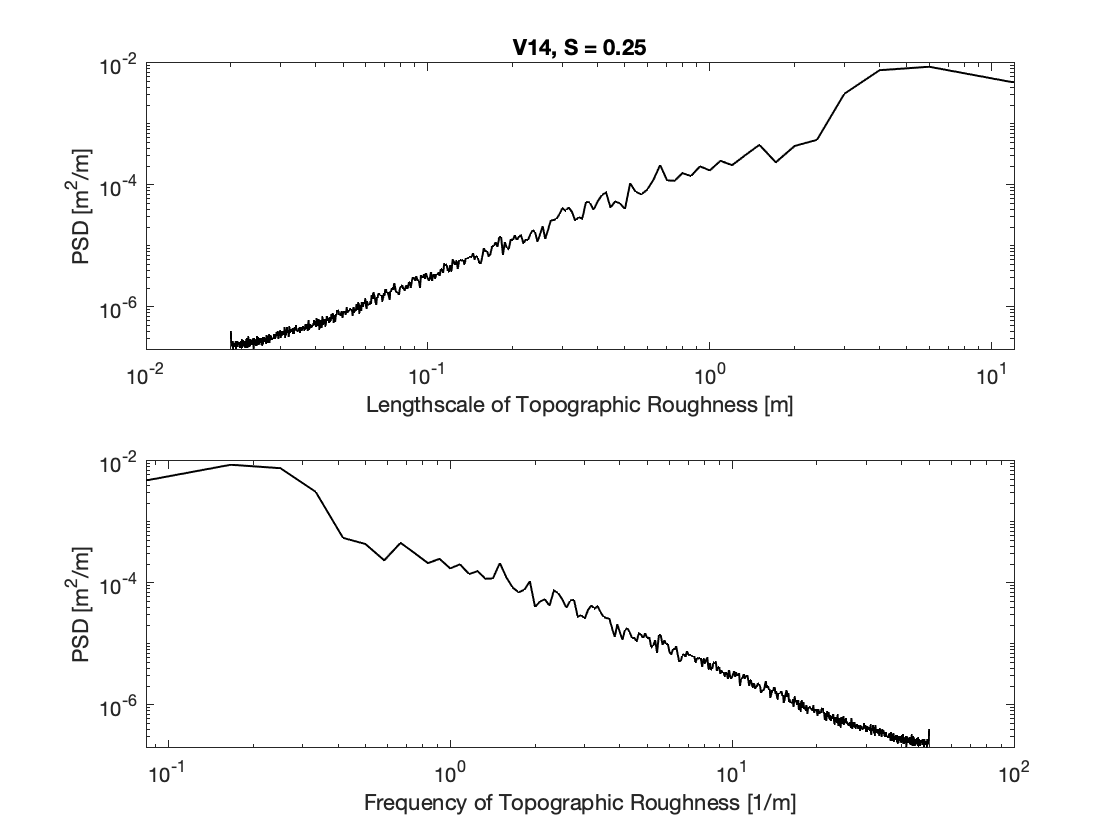

ans = 'V20'

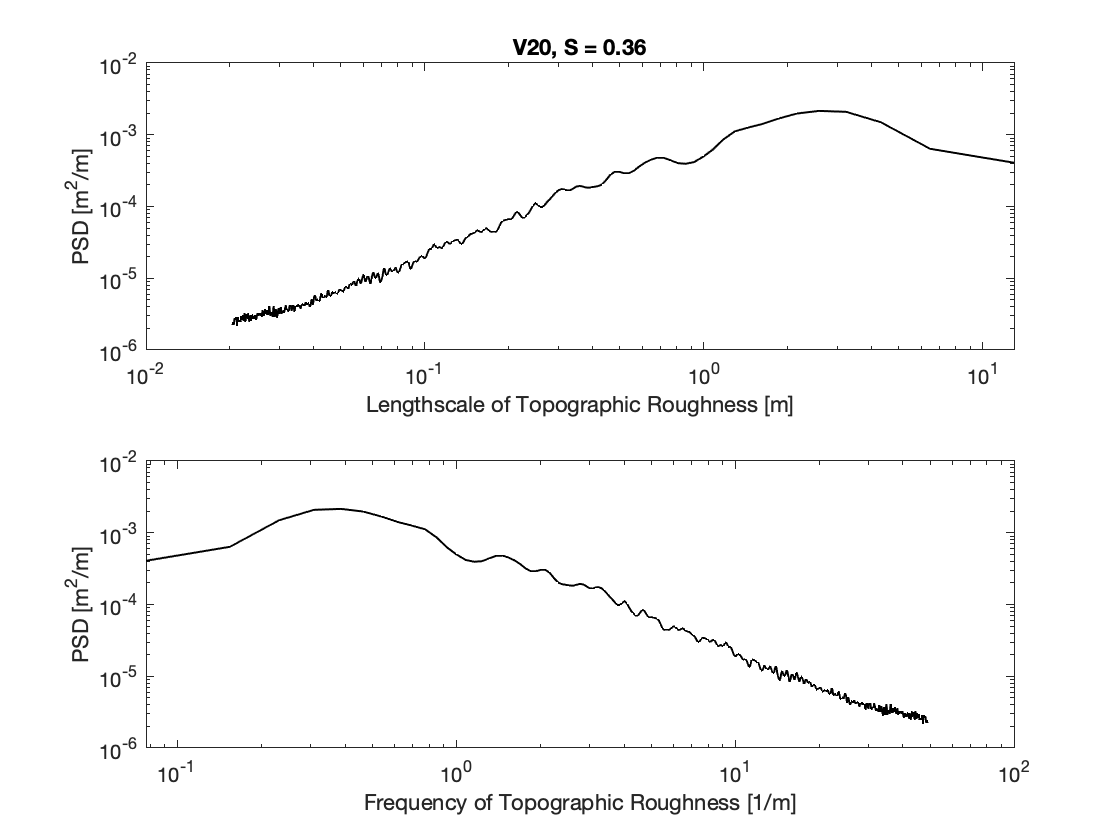

ans = 'V24'

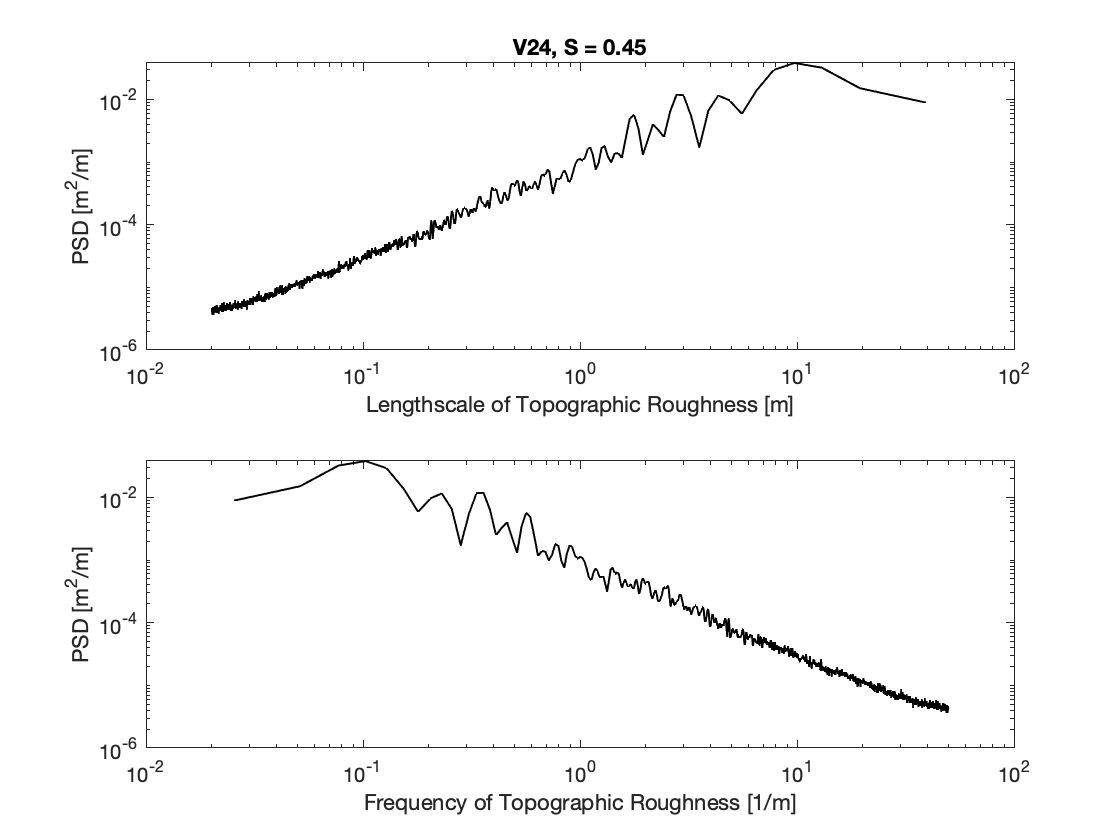

ans = 'V39'

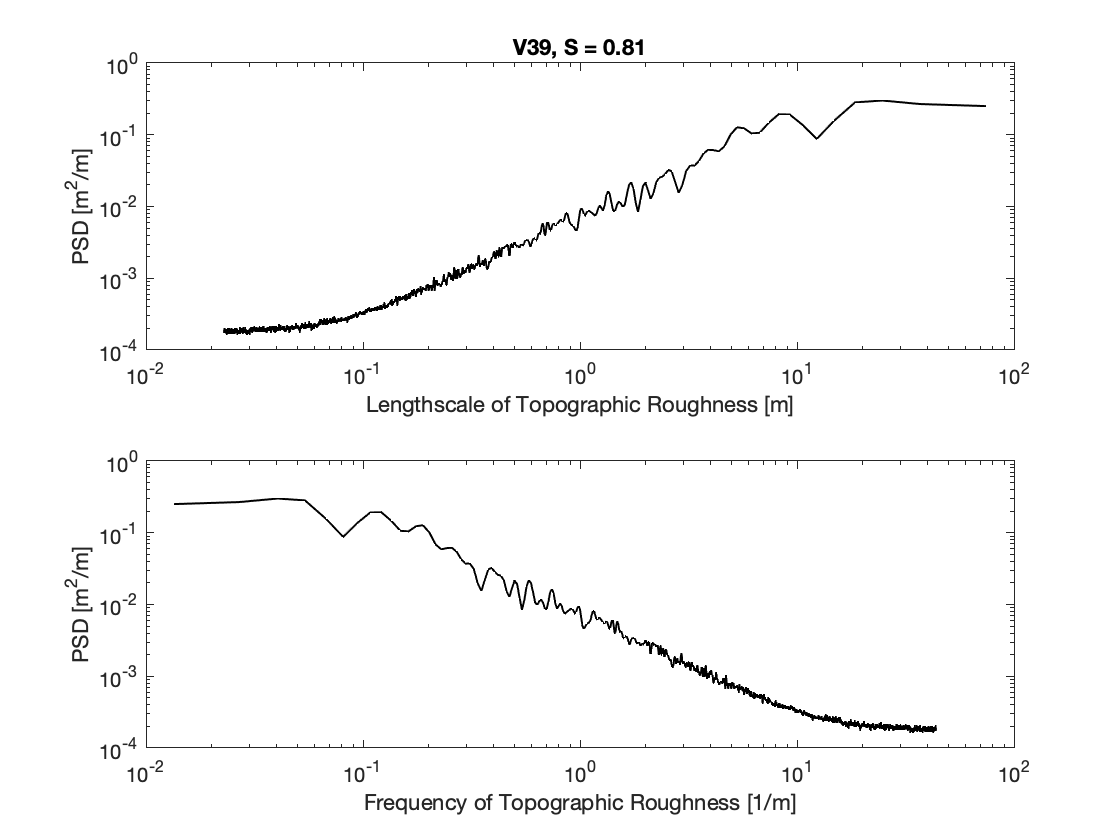

clear
% clf
% close all
load('/Users/danicaroth/Documents/Academic/Analysis/Nonlocal/RockDropData/final_XR.mat','Xfinal','Rfinal','CensorPoint');
dir='/Users/danicaroth/Documents/Academic/Analysis/Nonlocal/TopographicData/';
site={'H17c-avgz' 'H20c-avgz' 'H28c-avgz' 'N14c-avgz' 'N20c-avgz' 'N24c-avgz' 'N39c-avgz'};
iorder=[2 4 6 1 3 5 7]; %reorder colors from figure order from plot_rockdst_disentrainmentrate_FINAL.m
colors=[237 177 32; 179 177 32; 119 172 48; 119 172 48; 77 190 238; 0 131 205; 126 47 142]./255;%colors for plotting hi-pass
colors=colors(iorder,:);
CensorPoint=cell2mat(CensorPoint(iorder,:)); %final censor points used for each site and rock size, based on both slope breaks and tail data that overly biases lomax fit (e.g., due to collection of clasts at roots)
theta=0.1; %0 .1]; %theta (left truncation) at all sites = 0.1, but N24 starting line data was actually ~0.1m up from point cloud start
linestyle={'--' '--' '--' '-' '-' '-' '-' };
name = {'original' 'low-pass' 'high-pass'};
yt=[300;...%transect number (manually selected for each site)
    150;...
    120;...
    94;...
    220;...
    155;...
    304];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%% FILTER 1 CM SURFACE-NORMAL DISTANCES %%%%%%%%%%%%%%%%%%%

% Surface-normal (normal to bare-ground plane) distances are roughness
%heights in a surface-parallel reference frame.
% Use rasterized 1-cm data (constant point density) rather than    
%full point cloud (variable point density) to spatially normalize the 
%roughness probability.

clims=[];%0.2.*[-1 1];
cmap=lbmap(64,'RedBlue');

plot_topography = 'off';
plot_transects = 'off';
plot_spectra = 'on';
plot_roughnesswindowcomparison = 'off';
plot_roughnessCDF = 'off';

filtsigma =1*100; %gaussian filter sigma (in m) (converted to nelements or cm)
hsize =1*100; %gaussian filter window size (converted to nelements or cm)
hplegtext={};

for i = 1:7
    file=[dir,site{i},'-1cm-bgplaneN.tif'];
    Nraster{i}=(imread(file))';
    N.site{i}=[site{i},'-1cm-bgplaneN.tif'];
    N.slopedeg(i)=str2num(site{i}(2:3));
    N.slope(i)=tan(deg2rad(N.slopedeg(i)));
    Site{i} = N.site{i}(1:3); %print site name
    Site{i}(Site{i}(:)=='N')='V';
    Site{i}(Site{i}(:)=='H')='B';
    nx=size(Nraster{i},2); ny=size(Nraster{i},1);
    y = [1:ny]./100;   
    x = ([1:nx]./100);
    z = Nraster{i}(yt(i),:);
    x = x./cosd(N.slopedeg(i))-theta; %convert x to along-ground reference frame (matching travel distances) and shift by truncation distance (theta)
    cp(i)=max(CensorPoint(i,:)-.1); %make i-specific cp for easy reference later
   
    %FILTER RASTER
    Site{i}
    fig(i)=figure(i);
    clf
    [Nraster_lp{i},Nraster_hp{i},h,a,s,c] = nangaussfilt(Nraster{i},hsize,filtsigma,'clims',clims,'plot',plot_topography,'dx',.01,'dy',.01,'plotdim',1);
    raster={Nraster{i} Nraster_lp{i} Nraster_hp{i}};
    
    %Plot the topographic transects 
    if contains(plot_transects,'on')
        if contains(plot_topography,'on')
            figure(fig(i))
            for isub=1:3
                l(isub)=line([x(1) x(end)], [y(yt(i)) y(yt(i))],'Parent',s(isub));
                set(l(isub),'Color','k','linewidth',1,'ZData',max(z)*[1 1]+10);
            end
        end
        fig(i)=figure(i+10);
        clf
        plot(x,raster{2}(yt(i),:),'-s','linewidth',10,'Color',.7*[1 1 1]);
        hold on
        plot(x,raster{1}(yt(i),:),'k','linewidth',1,'LineStyle','-');
        plot(x,raster{3}(yt(i),:),'linewidth',1,'Color',colors(i,:),'LineStyle','-.');
        ylabel('z [m]')
        xlim([0 1.05*cp(i)]) %match axes with final figure 2 (x vs R)
        title([Site{i},', S = ',num2str(N.slope(i),2),'   (\sigma = ',num2str(filtsigma/100),' m, h = ',num2str(hsize/100),' m)'])
    end

    
    %SPECTRA
    if contains(plot_spectra,'on')  
        
        fig(i)=figure(i);
        %Calculate a 1D periodogram for each of these random samples
        fs = 1/.01; %units of samples/meter
        [PLz{i},fLz{i}] = plomb(raster{1}',fs);
%         [PLlp,fLlp] = plomb(raster{2}',fs);
%         [PLhp,fLhp] = plomb(raster{3}',fs);
        
        PLzm{i}=mean(PLz{i}');
%         PLlp=mean(PLlp');
%         PLhp=mean(PLhp');
        
        %turn frequency vectors into wavelength (= lengthscale of topographic roughness = 1/freq)
        wLz{i}=1./fLz{i};
%         wLlp=1./fLlp;
%         wLhp=1./fLhp;
        
        figure(fig(i))
        subplot(2,1,1)
        %Plot periodograms on loglog axes using wavelength instead of spatial frequency
        loglog(wLz{i},real(PLzm{i}),'k','linewidth',1,'LineStyle','-');
%         hold on
%         loglog(wLlp,real(PLlp),'linewidth',1,'Color','g','LineStyle','--');
%         loglog(wLhp,real(PLhp),'linewidth',1,'Color',colors(i,:),'LineStyle','-.');
        
        xlabel('Lengthscale of Topographic Roughness [m]')
        ylabel('PSD [m^2/m]')
        title([Site{i},', S = ',num2str(N.slope(i),2)]);

            
        
        %Plot periodograms on loglog axes using wavelength instead of spatial frequency
        subplot(2,1,2)
        loglog(fLz{i},real(PLzm{i}),'k','linewidth',1,'LineStyle','-');
        hold on
%         loglog(fLlp,real(PLlp),'linewidth',1,'Color','g','LineStyle','--');
%         loglog(fLhp,real(PLhp),'linewidth',1,'Color',colors(i,:),'LineStyle','-.');
        
        xlabel('Frequency of Topographic Roughness [1/m]')
        ylabel('PSD [m^2/m]')        
    end       
    
    figure(1)
    for i=1:7
        subplot(2,1,1)
        loglog(wLz{i},real(PLzm{i}),'Color',colors(i,:),'LineStyle',linestyle{i},'linewidth',1);
        hold on        
        xlabel('Lengthscale of Topographic Roughness [m]')
        ylabel('PSD [m^2/m]') 
        
        subplot(2,1,2)
        loglog(fLz{i},real(PLzm{i}),'Color',colors(i,:),'LineStyle',linestyle{i},'linewidth',1);
        hold on
        xlabel('Frequency of Topographic Roughness [1/m]')
        ylabel('PSD [m^2/m]')        
    end
    
    %ROUGHNESS WINDOW SENSITIVITY ANALYSIS (1)
    if contains(plot_roughnesswindowcomparison,'on')
        rwindow=[50:50:3000];
        for r=1:length(rwindow)
            Nraster_hpw{i}=[Nraster_hp{i}(:,1:min(rwindow(r),length(Nraster_hp{i}))) NaN(size(Nraster_hp{i},1),max(rwindow(r),size(Nraster_hp{i},2)))];
            [Fhpw,Rhpw]=ecdf(2.*abs(reshape(Nraster_hpw{i}(:,1:rwindow(r)),[1,size(Nraster_hpw{i},1)*rwindow(r)])));
            d50w(i,r)=prctile(2.*abs(reshape(Nraster_hpw{i}(:,1:rwindow(r)),[1,size(Nraster_hpw{i},1)*rwindow(r)])),50,'all');
            if rwindow(r) > size(Nraster_hp{i})
                d50w(i,r)=NaN;
            end
        end
        figure(8)
        plot(rwindow./100,d50w(i,:),'Color',colors(i,:),'LineStyle',linestyle{i}); hold on
        xlabel('roughness window [m]')
        ylabel('d_{50} [m]')
    end
    
    
    %ROUGHNESS DISTRIBUTIONS - PLOT CDFs (1) 
%     nx=size(Nraster{i},2); ny=size(Nraster{i},1);
%     y = [1:ny]./100;   
%     x = ([1:nx]./100);
%     z = Nraster{i}(yt(i),:);
% %     zs = z-(N.slope(i).*x); %re-trend elevations in horizontal reference frame
%     x = x./cosd(N.slopedeg(i))-itheta(i); 
    Nraster_hpcp{i}=Nraster_hp{i}(:,x>=0 & x<cp(i));
    Nraster_lpcp{i}=Nraster_lp{i}(:,x>=0 & x<cp(i));
    
    [Fhp{i},Rhp{i}]=ecdf(2.*abs(Nraster_hpcp{i}(:)));
    [Flp{i},Rlp{i}]=ecdf(2.*abs(Nraster_lpcp{i}(:)));
    d50(i)=prctile(2.*abs(Nraster_hpcp{i}(:)),50,'all');
    d50_std(i)=nanstd(2.*(reshape(Nraster_hpcp{i},[1,numel(Nraster_hpcp{i})])));
    Nd50(i)=numel(Nraster_hpcp{i});
    d50_serr(i)=d50(i)./sqrt(Nd50(i));

    if contains(plot_roughnessCDF,'on')
        %Plot roughness height distributions
        fhp=figure(9);
        ahp(i)=semilogx(Rhp{i},Fhp{i});
        set(ahp(i),'Color',colors(i,:),'LineStyle',linestyle{i});
        hold on
        
        flp=figure(10);
        alp(i)=semilogx(Rlp{i},Flp{i});
        set(alp(i),'Color',colors(i,:),'LineStyle',linestyle{i});
        hold on
            
        %Text for legends to be added later
        hplegtext=[hplegtext ['S = ',num2str(N.slope(i),2),',   d_{50}=',num2str(d50(i),2)]];
    end
end


%ROUGHNESS WINDOW SENSITIVITY ANALYSIS (2)
if contains(plot_roughnesswindowcomparison,'on')
    figure(8)
    plot(rwindow./100,d50w(i,:),'Color',colors(i,:),'LineStyle',linestyle{i}); hold on
    xlabel('roughness window [m]')
    ylabel('d_{50} [m]')
    
    for i=1:7
        Nd50w(i)=length(find(~isnan(d50w(i,:))));
    end
    d50w_std=nanstd(d50w');
    d50w_mean=nanmean(d50w');
    d50w_sensitivity=d50w_std./d50;
    d50w_serr=d50w_std./sqrt(Nd50w);
    d50w_prcserr=d50w_serr./d50;
end


%ROUGHNESS DISTRIBUTIONS - PLOT CDFs (2)
if contains(plot_roughnessCDF,'on')
    figure(9)
    leg=legend(hplegtext,'Location','NorthWest','FontSize',14);
    set(leg,'Box','off')
    xlim([0.0001 1])
    ylim([0 1])
    set(ahp,'LineWidth',1)
    title(['High-Pass Roughness Distributions (\sigma = ',num2str(filtsigma/100),' m, h = ',num2str(hsize/100),' m)']);
    xlabel('Roughness Height d (m)');
    ylabel('Cumulative Fraction');
    
    figure(10)
    xlim([0.0001 1])
    ylim([0 1])
    set(alp,'LineWidth',1)
    title(['Low-Pass Roughness Distributions (Gaussian Filter \sigma = 1 m)']);
    xlabel('Surface-Normal Filtered Height (m)');
    ylabel('Cumulative Fraction');
end


% save([dir,'roughness.mat'],'N','Fhp','Nhp','Flp','Nlp','Nraster_lp','Nraster_hp','filtsigma');
% save([dir,'rasters.mat'],'N','Nraster','Nraster_lp','Nraster_hp','filtsigma');
